t_max=1000

t_max = 1000

domain = [0 t_max];


g=10;
g_divs=60;
g_array=linspace(0.1*g,7*g,g_divs);
g_B=8;

A0B=6;
A0B_divs=60;
A0B_array=linspace(0.1*A0B,2*A0B,A0B_divs);
B0A=4;



%Number of samples to take 
r=6;
samplings=zeros(1,r);
%time array initialised
time_array=zeros(g_divs,A0B_divs);
cv_array=zeros(g_divs,A0B_divs);
for i=1:g_divs-1
    for j=1:A0B_divs
        for k=1:r
            A = 10*rand(1); 
            B = 10*rand(1); 
            [t, x] = ode45(@(t,x) interactions(t,x,g_array(i),A0B_array(j)),domain,[A;B]);
            u=[t,x(:,1)];
            samplings(k)=settling_time(u,t_max);
            
          
        end
        value=log(mean(samplings)/10);
        cv_array(i,j)=std(samplings)/mean(samplings);
        time_array(i,j)=value;
        
    end
end

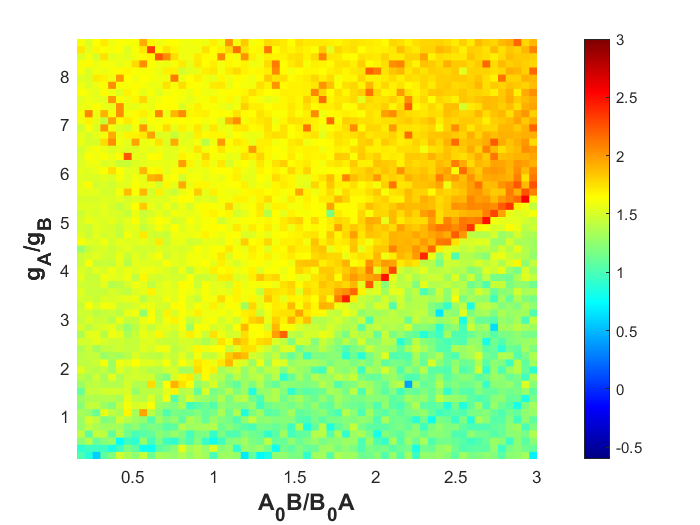

c=time_array ;
g_array=g_array./g_B;
A0B_array=A0B_array./B0A;
surf(A0B_array,g_array,time_array,'EdgeColor','none'), colormap jet,grid off,caxis([-0.6,3]), 
view([0.4 90.0])
ylim([min(g_array) max(g_array)])
xlim([min(A0B_array) max(A0B_array)])
colorbar
colorbar
xlabel('A_{0}B/B_{0}A',"FontSize",14,"FontWeight","bold","FontName",'Arial')
ylabel('g_A/g_B',"FontSize",14,"FontWeight","bold","FontName",'Arial')

function H = hill(X,X0,lambda,n)
% H+ 
H1 = (X^n)/(X0^n+X^n);
% H-
H2 = (X0^n)/(X0^n+X^n);

% Hill function =  H- plus (lambda)* H+
H = H2 + lambda*H1;

end


function dxdt = interactions(t,x,g_A,A0B)

% defining array of values for the time t: 
dxdt = zeros(2,1);

%% Paramaters
% Degradation rate:
gamma_A = 0.35;   gamma_B = 0.35;  

% Transcription rate/ Production rate:
%g_A = 10; 
g_B = 8;   

% Hills function threshold :
%A0B = 10;
B0A = 4;
A0A = 10;   B0B = 10;

% Cooperativity/ hill function coefficient:
nAtoB = 6;   nBtoA = 6;
nAtoA = 3;   nBtoB = 3;

% fold change/ lambda
lambda_AtoB = 0.1;   lambda_BtoA = 0.1;
lambda_AtoA = 3;   lambda_BtoB = 3;

%% equations:
% dxdt(1) = g_A*hill(x(1),A0A,lambda_AtoA,nAtoA)*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1) ;  %% equation A
% dxdt(2) = g_B*hill(x(2),B0B,lambda_BtoB,nBtoB)*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2) ; % equation B
% end
dxdt(1) = g_A*hill(x(2),B0A,lambda_BtoA,nBtoA) - gamma_A*x(1) ;  %% equation A
dxdt(2) = g_B*hill(x(1),A0B,lambda_AtoB,nAtoB) - gamma_B*x(2) ; % equation B
end


function t=settling_time(sol,t_max)
x=sol(:,2);
flag=0;
for i=1:length(x)
    if abs(x(i)-x(i+5))<0.01
        flag=1;
    end
    if flag==1
        t=i;
        break
    end
end
if flag==0
    t=t_max;
end
end